Logical Operations

**SoC Vector Simulation (Manually Given or Linearly Dropped)**

%% Simulated SoC Data
time = 0:10:300    % Time vector in seconds (30 points)

time =      0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280   290   300


soc = linspace(100, 40, length(time))   % SoC drops from 100% to 40%

soc =    100    98    96    94    92    90    88    86    84    82    80    78    76    74    72    70    68    66    64    62    60    58    56    54    52    50    48    46    44    42    40


**Plot SoC vs. Time**

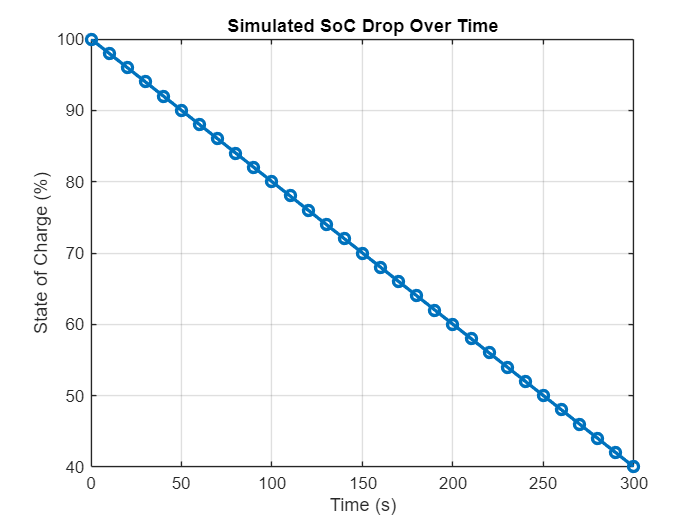

plot(time, soc, '-o', 'LineWidth', 2)
xlabel('Time (s)')
ylabel('State of Charge (%)')
title('Simulated SoC Drop Over Time')
grid on

**Logical Operation: Find When SoC Drops Below 60%**

%% Find Low SoC Points
low_soc_mask = soc < 60           % Logical array

low_soc_mask = 1×31 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1


low_soc_indices = find(low_soc_mask)  % Index positions

low_soc_indices =     22    23    24    25    26    27    28    29    30    31


low_soc_values = soc(low_soc_mask)   % Actual SoC values

low_soc_values =     58    56    54    52    50    48    46    44    42    40


**Display and Highlight on Plot**

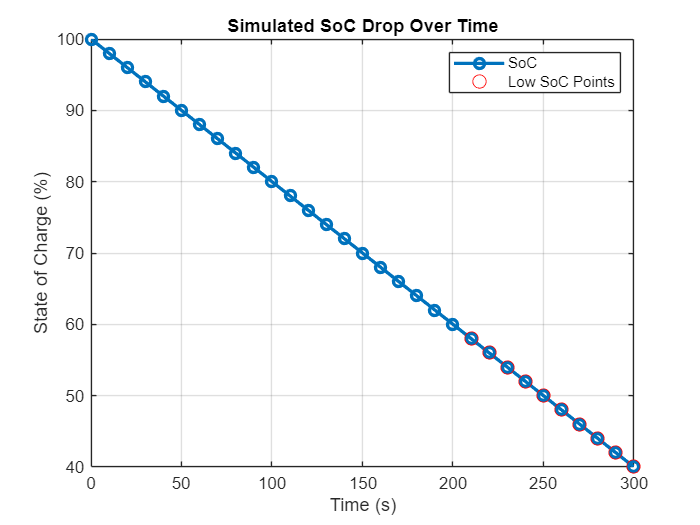

%% Highlight on Plot
hold on
plot(time(low_soc_mask), soc(low_soc_mask), 'ro', 'MarkerSize', 8, 'DisplayName', 'Low SoC')
legend('SoC', 'Low SoC Points')
hold off

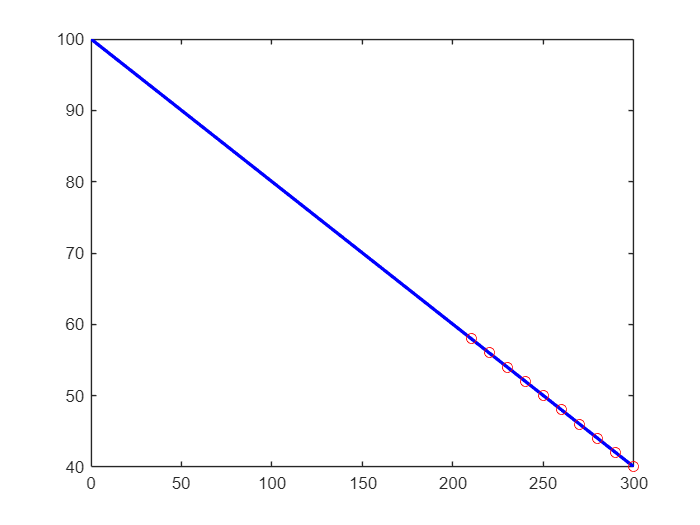

plot(time, soc, 'b', 'LineWidth', 2)     % Plot original SoC
hold on                                  % Keep current plot
plot(time(soc < 60), soc(soc < 60), 'ro') % Overlay low SoC points
hold off                                 % Done adding overlays

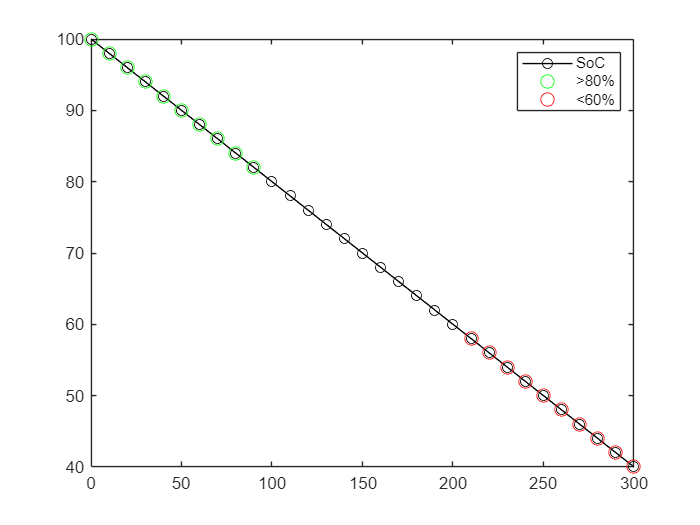

plot(time, soc, 'k-o')      % Plot original
hold on
plot(time(soc > 80), soc(soc > 80), 'go', 'MarkerSize', 8)
plot(time(soc < 60), soc(soc < 60), 'ro', 'MarkerSize', 8)
hold off
legend('SoC','>80%','<60%')